# Controller Calculations

## Load model

dir = "..\data\model\";

Phi = readmatrix(dir + 'Phi.dat');
Gamma = readmatrix(dir + 'Gamma.dat');
C = readmatrix(dir + 'C.dat');
D = readmatrix(dir + 'D.dat');
h = readmatrix(dir + 'h.dat');

clear dir

## Controller Design

Manual pole placement

% poles = [0.8, 0.8, 0.8, 0.8];
% K = acker(Phi,Gamma,poles)

Linear quadratic optimal design

Phi_aug = [Phi zeros(size(Phi, 1), 1); 0 0 0 -h 1];
Gamma_aug = [Gamma; 0];

% State weights
Q_lqr =[10 0 0 0 0; % tilt vel
        0 1e4 0 0 0; % tilt angle
        0 0 1 0 0; % wheel vel
        0 0 0 1 0; % wheel angle
        0 0 0 0 .1]; % Integral action

% Controller output weight
R_lqr = .1;  % motor voltage

K = dlqr(Phi_aug, Gamma_aug, Q_lqr, R_lqr)

K =   -12.4019  -78.9312   -1.0071   -0.5351    0.1199


Kalman Filter

% Process input noise covariance
Q_kal = [10 0; % Tilt dynamics
         0 1]; % Wheel dynamics

% Measurement noise covariance
R_kal = [1e-9 0 0; % tilt vel
         0 1e-9 0; % tilt angle
         0 0 1e-9]; % wheel angle

N_kal = 0;

Phi_kal = [1 0 0 0;
           h 1 0 0;
           0 0 1 0;
           0 0 h 1];

G = [h 0;
     0 0;
     0 h;
     0 0];

Gamma_kal = G; % B is assumed to be 0 in this simplified model (Input is only the noise that is assumed to contain the system's input)

C_kal = C;

D_kal = zeros(size(D, 1), size(Gamma_kal, 2));

sys_kal = ss(Phi_kal, Gamma_kal, C_kal, D_kal, h);
[~, L, ~, Mx] = kalman(sys_kal, Q_kal, R_kal, N_kal, "current");

Feedforward

% State weights
Q_ff =[1 0 0 0; % tilt vel
       0 1 0 0; % tilt angle
       0 0 1 0; % wheel vel
       0 0 0 1]; % wheel angle

% Controller output weight
R_ff = 100;  % feed forward voltage

K_m = dlqr(Phi, Gamma, Q_ff, R_ff);
K_c = 1 / ([0 0 0 1] * ((eye(size(Phi)) - Phi + Gamma * K_m) \ Gamma));

Precalculation

decimals = 8;

ControlGain = round(K, 3);
ObserverGain = round(L, decimals);
ObserverPhi = round(Phi_kal - L*C_kal, decimals);
ObserverInnoGain = round(Mx, decimals);
FeedForwardModelPhi = round(Phi, decimals);
FeedForwardModelGamma = round(Gamma, decimals);
FeedForwardKm = round(K_m, decimals);
FeedForwardKc = round(K_c, decimals);

% Comment in to change K values manually
% ControlGain(1) = -12;
% ControlGain(2) = -200;
% ControlGain(3) = 0;
% ControlGain(4) = 0;
% ControlGain(5) = 0;

% Comment in to bypass Kalman filter
% ObserverPhi = zeros(size(Phi_k, 1), size(Phi_k, 2));
% ObserverGain = zeros(size(L, 1), size(L, 2));
% ObserverInnoGain = eye(size(Mx, 1), size(Mx, 2));

% Comment in to bypass feedforward extension
% FeedForwardModelPhi = zeros(size(Phi));
% FeedForwardModelGamma = zeros(size(Gamma));
% FeedForwardKm = zeros(1, size(Phi, 1));
% FeedForwardKc = 0;

## Evaluation

Poles

disp('Control Poles: ')

Control Poles: 


disp(eig(Phi_aug - Gamma_aug * K))

    0.0000
    0.8986
    0.9721
    0.9904
    0.9966



disp('Feedforward Model Poles: ')

Feedforward Model Poles: 


disp(eig(Phi - Gamma * K_m))

    0.0004
    0.9439
    0.9457
    0.9977



Simulation

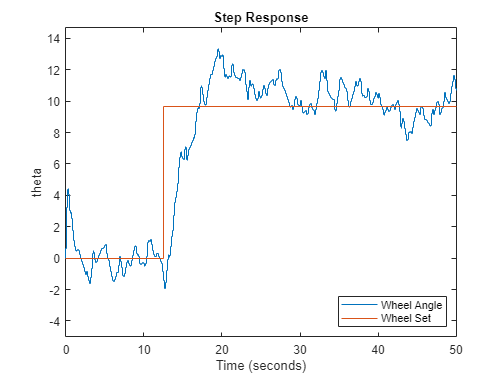

initial_state = [0; 0.2; 0; 0; 0];
cm_to_rad = 2*pi/13;
step_size_cm = 20;

sim_time_sec = 50;
controller_sim = sim("simulation.slx");
plot(controller_sim.theta)
hold on
plot(controller_sim.z)
hold off
axis([0 sim_time_sec -5 step_size_cm * cm_to_rad + 5])
title 'Step Response'
legend("Wheel Angle", "Wheel Set", 'Location', 'southeast')

## Save calculations

Load parameter interface

parameters = jsondecode(fileread("..\interface.json"));
parameters = parameters.TO_DEVICE.parameters;

Set parameters here

parameters.variable.General.h_ms = h * 1e3;
parameters.variable.General.alpha_off = -0.012;
parameters.variable.General.m_stop = 1;
parameters.variable.General.m_start = 30;

parameters.variable.BalanceControl.k1 = ControlGain(1);
parameters.variable.BalanceControl.k2 = ControlGain(2);
parameters.variable.BalanceControl.k3 = ControlGain(3);
parameters.variable.PositionControl.k4 = ControlGain(4);
parameters.variable.PositionControl.ki = ControlGain(5);

parameters.inferred.observer.gain.l11 = ObserverGain(1, 1);
parameters.inferred.observer.gain.l12 = ObserverGain(1, 2);
parameters.inferred.observer.gain.l13 = ObserverGain(1, 3);
parameters.inferred.observer.gain.l21 = ObserverGain(2, 1);
parameters.inferred.observer.gain.l22 = ObserverGain(2, 2);
parameters.inferred.observer.gain.l23 = ObserverGain(2, 3);
parameters.inferred.observer.gain.l31 = ObserverGain(3, 1);
parameters.inferred.observer.gain.l32 = ObserverGain(3, 2);
parameters.inferred.observer.gain.l33 = ObserverGain(3, 3);
parameters.inferred.observer.gain.l41 = ObserverGain(4, 1);
parameters.inferred.observer.gain.l42 = ObserverGain(4, 2);
parameters.inferred.observer.gain.l43 = ObserverGain(4, 3);

parameters.inferred.observer.phi.phi11 = ObserverPhi(1, 1);
parameters.inferred.observer.phi.phi12 = ObserverPhi(1, 2);
parameters.inferred.observer.phi.phi13 = ObserverPhi(1, 3);
parameters.inferred.observer.phi.phi14 = ObserverPhi(1, 4);
parameters.inferred.observer.phi.phi21 = ObserverPhi(2, 1);
parameters.inferred.observer.phi.phi22 = ObserverPhi(2, 2);
parameters.inferred.observer.phi.phi23 = ObserverPhi(2, 3);
parameters.inferred.observer.phi.phi24 = ObserverPhi(2, 4);
parameters.inferred.observer.phi.phi31 = ObserverPhi(3, 1);
parameters.inferred.observer.phi.phi32 = ObserverPhi(3, 2);
parameters.inferred.observer.phi.phi33 = ObserverPhi(3, 3);
parameters.inferred.observer.phi.phi34 = ObserverPhi(3, 4);
parameters.inferred.observer.phi.phi41 = ObserverPhi(4, 1);
parameters.inferred.observer.phi.phi42 = ObserverPhi(4, 2);
parameters.inferred.observer.phi.phi43 = ObserverPhi(4, 3);
parameters.inferred.observer.phi.phi44 = ObserverPhi(4, 4);

parameters.inferred.observer.innoGain.mx11 = ObserverInnoGain(1, 1);
parameters.inferred.observer.innoGain.mx12 = ObserverInnoGain(1, 2);
parameters.inferred.observer.innoGain.mx13 = ObserverInnoGain(1, 3);
parameters.inferred.observer.innoGain.mx21 = ObserverInnoGain(2, 1);
parameters.inferred.observer.innoGain.mx22 = ObserverInnoGain(2, 2);
parameters.inferred.observer.innoGain.mx23 = ObserverInnoGain(2, 3);
parameters.inferred.observer.innoGain.mx31 = ObserverInnoGain(3, 1);
parameters.inferred.observer.innoGain.mx32 = ObserverInnoGain(3, 2);
parameters.inferred.observer.innoGain.mx33 = ObserverInnoGain(3, 3);
parameters.inferred.observer.innoGain.mx41 = ObserverInnoGain(4, 1);
parameters.inferred.observer.innoGain.mx42 = ObserverInnoGain(4, 2);
parameters.inferred.observer.innoGain.mx43 = ObserverInnoGain(4, 3);

parameters.inferred.ff.phi.phi11 = FeedForwardModelPhi(1, 1);
parameters.inferred.ff.phi.phi12 = FeedForwardModelPhi(1, 2);
parameters.inferred.ff.phi.phi13 = FeedForwardModelPhi(1, 3);
parameters.inferred.ff.phi.phi14 = FeedForwardModelPhi(1, 4);
parameters.inferred.ff.phi.phi21 = FeedForwardModelPhi(2, 1);
parameters.inferred.ff.phi.phi22 = FeedForwardModelPhi(2, 2);
parameters.inferred.ff.phi.phi23 = FeedForwardModelPhi(2, 3);
parameters.inferred.ff.phi.phi24 = FeedForwardModelPhi(2, 4);
parameters.inferred.ff.phi.phi31 = FeedForwardModelPhi(3, 1);
parameters.inferred.ff.phi.phi32 = FeedForwardModelPhi(3, 2);
parameters.inferred.ff.phi.phi33 = FeedForwardModelPhi(3, 3);
parameters.inferred.ff.phi.phi34 = FeedForwardModelPhi(3, 4);
parameters.inferred.ff.phi.phi41 = FeedForwardModelPhi(4, 1);
parameters.inferred.ff.phi.phi42 = FeedForwardModelPhi(4, 2);
parameters.inferred.ff.phi.phi43 = FeedForwardModelPhi(4, 3);
parameters.inferred.ff.phi.phi44 = FeedForwardModelPhi(4, 4);

parameters.inferred.ff.gamma.gam1 = FeedForwardModelGamma(1);
parameters.inferred.ff.gamma.gam2 = FeedForwardModelGamma(2);
parameters.inferred.ff.gamma.gam3 = FeedForwardModelGamma(3);
parameters.inferred.ff.gamma.gam4 = FeedForwardModelGamma(4);

parameters.inferred.ff.Km.k1 = FeedForwardKm(1);
parameters.inferred.ff.Km.k2 = FeedForwardKm(2);
parameters.inferred.ff.Km.k3 = FeedForwardKm(3);
parameters.inferred.ff.Km.k4 = FeedForwardKm(4);

parameters.inferred.ff.Kc = FeedForwardKc;

Choose a name for this parameter set

SET_NAME = "testing";

Encode to json and write to file

path = "..\data\parameters\" + SET_NAME + ".json";
if isfile(path)
    answer = questdlg("The file " + path + " already exists. Do you want to overwrite?");
    switch answer
        case 'Yes'
            disp("File will be overwritten.")
        otherwise
            disp("Aborting.")
            return
    end
end

File will be overwritten.


writelines(jsonencode(parameters, PrettyPrint=true), path);
clear answer file path